clear ;
close all;
type=2;                                         %信源类型
a=0.3;                                          %滚降系数
L=1000;                                       %信源长度

x=makingData(type,L);                           %信源
x2=AMI_Code(type,x);                            %码型转换为AMI码
y=extrudeMultiples(x2,20);                      %周期扩大20倍
hn=rcosdesign(0.3,6,4,'sqrt');                  %建立升余弦滚降滤波器%M长度为25
send1=filterDeal(y,hn);                         %通过发送滤波器

p=(10);
for i=0:9
    get2=filterDeal(addNoise(i,send1,x),hn);    %添加噪声+经过接收滤波器
    p(i+1)=errorRate(AMItoBinary(type,judgeCode(type,sample_AY(get2,20))),x); %采样+判决+码型反转+计算误码率
end

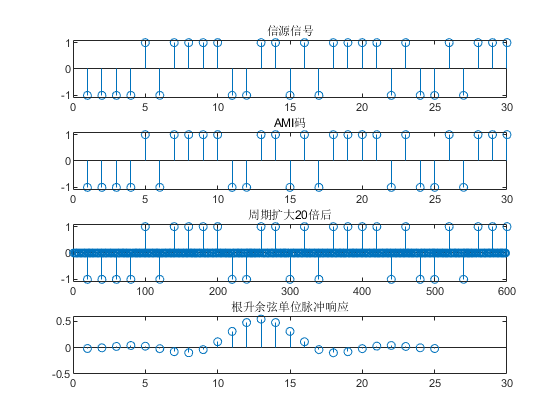

%% 以下用于绘制图形 %%
SNR=10;                                          %设置信噪比  
send2=addNoise(SNR,send1,x);                     %在send1上添加噪声
send3=filterDeal(send2,hn);                      %通过接收滤波器

ER=0;
send4=sample_AY(send3,20);                       %对send3抽样
send5=judgeCode(type,send4);                        %判决
send6=AMItoBinary(type,send5);                      %码型反转
pp=errorRate(send6,x);

figure(1);
subplot(4,1,1);stem(x);axis([0 30 -1.1 1.1]);title("信源信号");
subplot(4,1,2);stem(x2);axis([0 30 -1.1 1.1]);title("AMI码");
subplot(4,1,3);stem(y);axis([0 600 -1.1 1.1]);title("周期扩大20倍后");
subplot(4,1,4);stem(hn);axis([0 30 -0.5 0.6]);title("根升余弦单位脉冲响应");

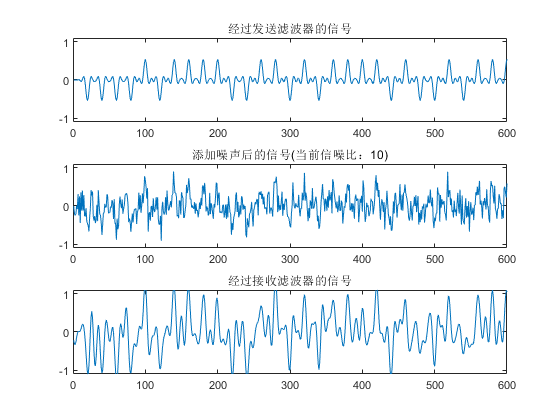


figure(2);
subplot(3,1,1);plot(send1);axis([0 600 -1.1 1.1]);title("经过发送滤波器的信号");
subplot(3,1,2);plot(send2);axis([0 600 -1.1 1.1]);title(sprintf("添加噪声后的信号(当前信噪比：%d)",SNR));
subplot(3,1,3);plot(send3);axis([0 600 -1.1 1.1]);title("经过接收滤波器的信号");

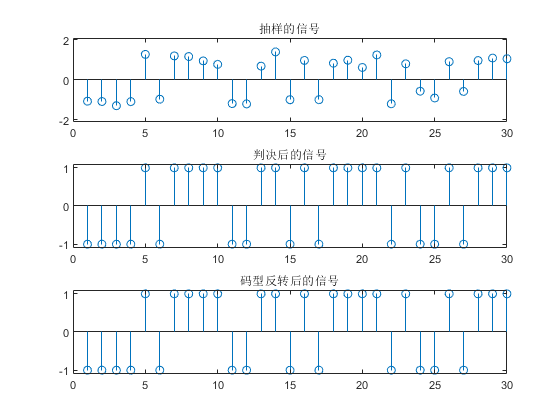

figure(3);
subplot(3,1,1);stem(send4);axis([0 30 -2.1 2.1]);title("抽样的信号");
subplot(3,1,2);stem(send5);axis([0 30 -1.1 1.1]);title("判决后的信号");
subplot(3,1,3);stem(send6);axis([0 30 -1.1 1.1]);title("码型反转后的信号");

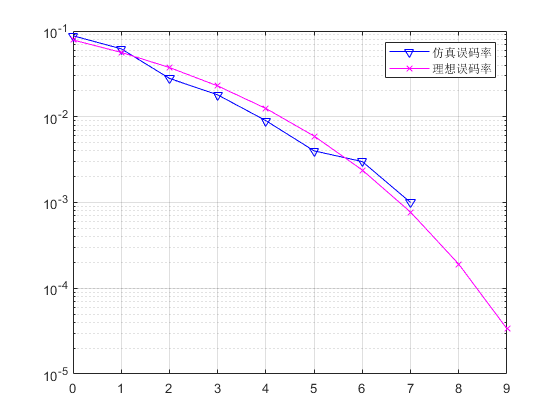


figure(4);
m=(0:1:9);                                      %信噪比
j=1:10  ; 
TBER(j) = erfc (sqrt(power(10,m(j)/10)))/2;     %理论误码率
semilogy(m,p,'B-V',m,TBER,'M-X');
grid on;
legend ('仿真误码率','理想误码率');

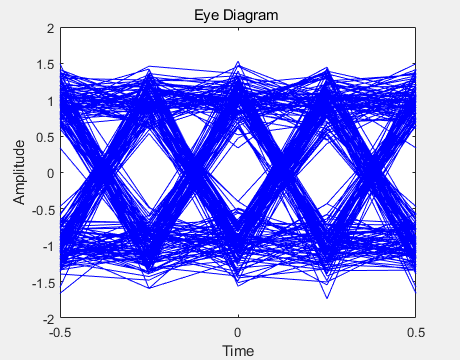


figure(5);
eyediagram(send4,4,1,0);

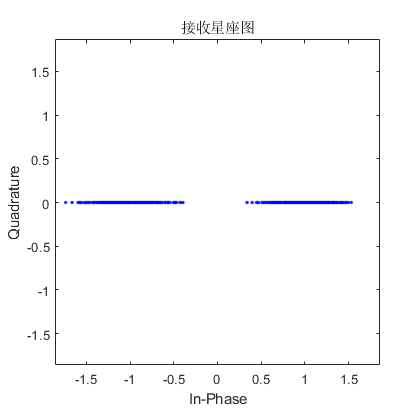

scatterplot(send4);title('接收星座图');